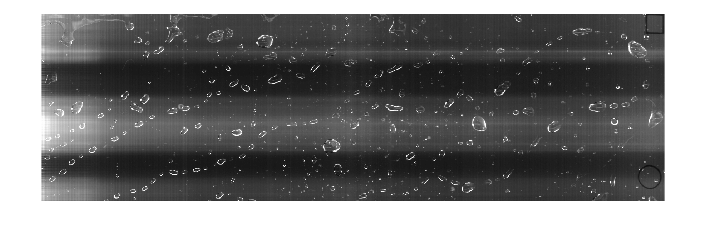

% Get image for analyzing
source_img = im2gray(imread('_IMAG0003.JPG'));
imshow(source_img)

relImg = double(source_img)./256;

### Radon transformation

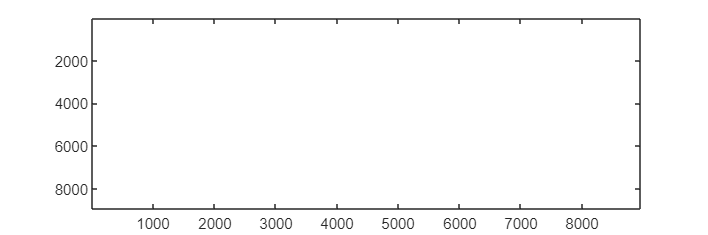

I = zeros(8960,8960); % 16384*16384

I(1:2688,1:8960) = relImg;
imagesc(I,[0 1]);
colormap(gray);


theta = 0:179;
[R,xp] = radon(I,theta);

imshow(R,[],'Ydata',theta,'Xdata',xp,'InitialMagnification','fit')
ylabel('\theta (degrees)')
xlabel('x''')
colormap(gca,hot), colorbar

iptsetpref('ImshowAxesVisible','off')

### Save only necessary angles

% angle range
delta_angle = 1;

R(:,3:88) = 0;
R(:,91:179) = 0;

line_img = iradon(R,theta)

line_img =    -2.1643    2.6895    1.3634    0.9689    0.7380    0.6771    0.5555    0.4907    0.4332    0.3832    0.3928    0.3945    0.3808    0.3879    0.3803    0.3853    0.3609    0.4340    0.3826    0.3380    0.2743    0.2358    0.2266    0.2367    0.2261    0.2445    0.2625    0.3264    0.3870    0.4107    0.4013    0.3786    0.4016    0.2753    0.3349    0.3452    0.3290    0.3141    0.3050    0.2992    0.2665    0.3780    0.3617    0.3771    0.3664    0.3415    0.3219    0.3362    0.3282    0.3007
   -2.1668    2.6918    1.3676    0.9744    0.7453    0.6859    0.5661    0.5031    0.4474    0.3994    0.4110    0.4146    0.4031    0.4114    0.4054    0.4125    0.3900    0.4650    0.4156    0.3726    0.3109    0.2742    0.2673    0.2791    0.2706    0.2907    0.3109    0.3767    0.4391    0.4647    0.4571    0.4362    0.4602    0.3346    0.3951    0.4058    0.3902    0.3762    0.3681    0.3631    0.3313    0.4439    0.4286    0.4450    0.4353    0.4111    0.3926    0.4080    0.39

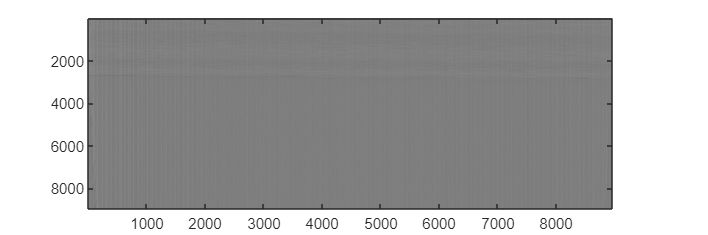

imagesc(line_img);

### Image enchancement

### Image binarization

threshold = 80;
% relative intensity
relThresh = threshold/256;

bw = imbinarize(source_img,relThresh);
imshow(bw)

%mean(source_img,'all')

% Morphological structuring element - disk
% disk mask decomposition
%closeRadius = 40;
%decomposition = 8;
%se = strel('disk', closeRadius, decomposition);

% img = source_img
img = wiener2(source_img);
img = adapthisteq(img);
montage({source_img, img},'Size', [2 1]);

% level = multithresh(img);

threshold = 180;
% relative intensity
relThresh = threshold/256;

bw = imbinarize(img,relThresh);
bw = imclearborder(bw);
% close mask with disk
bw = imclose(bw, se);
bw = imfill(bw, 'holes');
imshow(bw)
%binImg = edge(bw, 'Canny', relThresh);
%imshow(binImg)